# Synchronization Algorithms implementation

### Introduction

From previous script, we have seen and implemented the main issues of synchronization. The aim of this script is to correct those errors. To do so, 2 main algorithms are needed : the gardner algorithm to track the correct time instant to sample and the DA frame acquisition to remove CFO and phase shift. 

The first algorithm to be implemented is the NDA (Non Data Aided) Gardner algorithm because this algorithm is resistant to both CFO and phase shift. CFO and phase shift will be corrected by the DA frame acquisition.  

clc; close all; clearvars;
addpath("/MATLAB Drive/ELEC-H401-DVB-S2/1 Optimal communication channel");

%% parameters
Nbit = 1800;
Nbps = 1;    %Nombre of bits per symbol (1 = BPSK, 2 = 4QAM, 4 = 16QAM, 6 = 64QAM)
f_cut = 1e6; %Hz Cutoff frequency
fsymb = 2*f_cut;
T_symb = 1/fsymb;
fsamp = 8*fsymb; % Sampling frequency (rule of thumb for the 10 25 times f_cut) Its the freq on which the conv of the filter and the signal will be done --> has to be the same !!!
M = 16; %Upsampling factor (au moins plus grand que 4) multiple de fsamp
EbNo = 6; %Energy of one by over the PSD of the noise ratio (in dB)
N_taps = 101; %number of taps of the filter
beta = 0.3; %Makes the window smoother as beta increases // roll-off factor given in the specifications
%% Bit Generator

bits = randi(2,1,Nbit)-1;
check_mult = mod(Nbit,Nbps);
if check_mult == 0
    bit_tx = bits;
else
    bit_tx = [bits  zeros(1,Nbps - check_mult)];
end
Nbit_tx = length(bit_tx);

%% Mapping
%Maps the bits into desired symbols in the complex plane 
if (Nbps > 1)
    symb_tx = mapping(bit_tx', Nbps, 'qam')';
else
    symb_tx = mapping(bit_tx', Nbps, 'pam')';
end

%figure(12); grid on; title("Mapped signal in absolute value"); stem(abs(symb_tx));
%% Upsampling

upsampled_symb_tx = UpSampling(symb_tx,Nbit_tx,Nbps,M);


%% Transmitter Filter

filter = HalfrootNyquistFilter(fsamp,T_symb,N_taps); %So we compute de filter only 1 time as this is the same

signal_tx = conv(upsampled_symb_tx,filter);%Convolution of the signal with the filter
signal_tx1 = conv(upsampled_symb_tx(1:M),filter);


%figure(7); stem(abs(signal_tx)); title("transmited signal")
%signal_tx = upsampled_symb_tx;


%% Transmission Channel

signal_rx = NoiseAddition(signal_tx,EbNo,fsamp,Nbit);      %With Noise
%signal_rx = signal_tx;                              %Without Nosie

% signal_rx1 = NoiseAddition(signal_tx1,EbNo,fsamp,Nbps);      %With Noise
signal_rx1 = signal_tx1;      %With Noise

%fig_signal_tx = figure('Name','signal_tx','NumberTitle','off');plot(signal_rx,'b.');grid on;hold on;plot(signal_tx,'ro');


%% CFO and phase shift addition
fs_passband= 2e9; %Hz
CFO = 2; % CFO in ppm (2 to see something)
CFO = fs_passband*CFO*1e-6; %CFO in Hz
[signal_rx_CFO, phase_shift, time_shift] = Add_sync_errors(signal_rx,CFO,fsamp,M,Nbps);
%figure;subplot(1,2,1); scatter(real(signal_rx_CFO),imag(signal_rx_CFO)); axis equal; title("CFO and phase shift effects"); legend("CFO and phase shift"); subplot(1,2,2); scatter(real(signal_rx),imag(signal_rx)); axis equal; legend( "No CFO and phase shift")

%% Matched filter 
matched_filter = flip(filter); %Get the time reversal of the filter g(-t) 
upsampled_signal_rx = conv(signal_rx_CFO,matched_filter,'valid');
vanilla_upsampled_signal = conv(signal_rx,matched_filter,'valid');

### The Gardner Algorithm

*Code is in the GardnerDownsampler function*

The feedback loop implementation of the Gardner algorithm follows this recursive equation : 

## 
$$\hat{\epsilon}[n+1] = \hat{\epsilon}[n]+2 \kappa \Re\left[y_{\hat{\epsilon}[n]}[n-1 / 2]\left(y_{\hat{\epsilon}[n]}^{*}[n]-y_{\hat{\epsilon}[n-1]}^{*}[n-1]\right)\right]

(1)$$


##  Where $y_{\epsilon}[n] := \int^{\infty}_{-\infty}{r(t)g^{*}(t-nT -\epsilon T)} (2)$ 

In this code, $y_\epsilon [n]
$ is `signal_rx `and $\epsilon$ is the `time_shift `given in indices. 

(1) is interpreted has the estimation of the correct sample time shift. Once this time shift maximizes the signal energy, it is assumed to be the correct time shift.

We have to add the time shift in the matched filter to get (2) We therefore have to get rid of it after the matched filter.

The following graph shows how the algorithm works. 

## 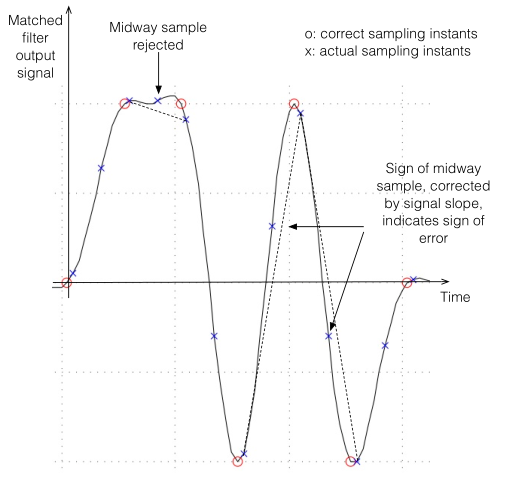

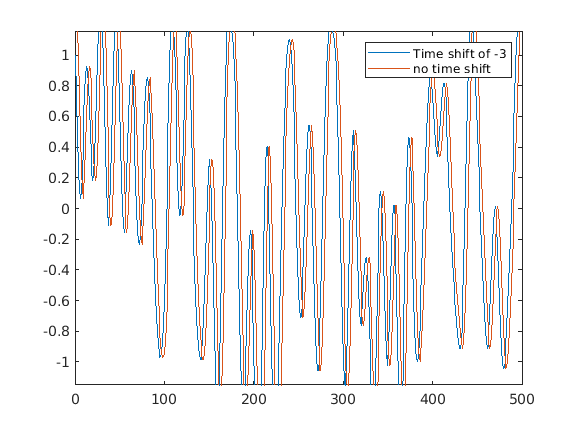

kappa = 0.02; %correction slope coefficient trade off time/noise reduction
figure; plot(real(upsampled_signal_rx)); hold on; plot(real(vanilla_upsampled_signal));
legend("Time shift of "+string(time_shift)  ,"no time shift");
xlim([0 500])
ylim([-1.15 1.15])

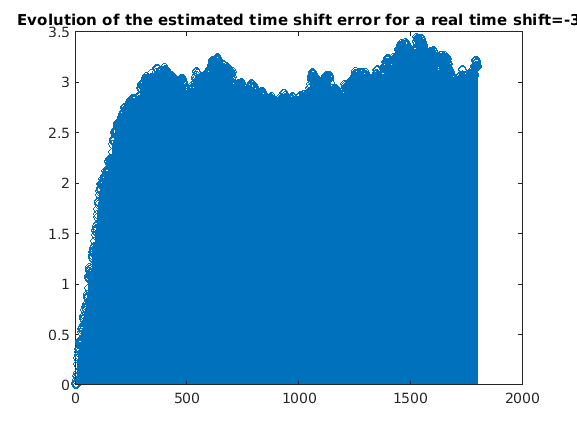


%upsampled_gardned_signal_rx = signal_rx_CFO;


[symb_rx,eps_hat] = Gardner(upsampled_signal_rx,M,kappa);
figure; stem(eps_hat);title("Evolution of the estimated time shift error for a real time shift="+string(time_shift));

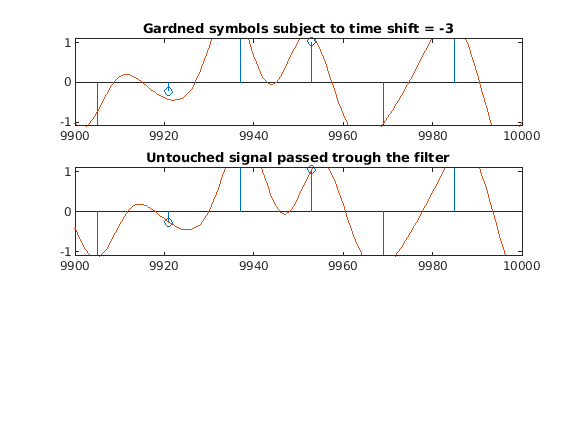


%% Downsampling
%symb_rx = DownSampling(upsampled_gardned_signal_rx,Nbit_tx,Nbps,M);
symb_rx_vanilla = DownSampling(vanilla_upsampled_signal,Nbit_tx,Nbps,M);
figure; subplot(3,1,1); stem(1:M:Nbit*M,real(symb_rx));hold on; plot(real(upsampled_signal_rx)); title("Gardned symbols subject to time shift = "+string(time_shift));
subplot(3,1,2);stem(1:M:Nbit*M,real(symb_rx_vanilla));hold on; plot(real(vanilla_upsampled_signal)); title("Untouched signal passed trough the filter");

subplot(3,1,1)
xlim([9900 10000])
ylim([-1.10 1.10])
subplot(3,1,2)
xlim([9900 10000])
ylim([-1.10 1.10])


%% Demapping
 
if (Nbps > 1)
    bit_rx = demapping(symb_rx', Nbps, 'qam')';
else
    bit_rx = demapping(real(symb_rx)', Nbps, 'pam')';
end

bit_down_scaled = bit_rx(1:Nbit);

%% Bits check

ErrorRatio = ErrorCalculator(bit_rx,bit_tx)

ErrorRatio = 0.0044

%figure; plot(symb_tx-symb_rx);title("error between symb_rx and symb_tx");

blublub